## TP1 Telecom

close all;
clear all;

### **Initialization**

nb_bits = 2000; % On génère 2000 bits
bits = randi([0,1],1,nb_bits); % Les 2000 bits seront compris entre 0 et 1
Fe = 24000; % Fs, fréquence d'échantillonage
Rb = 6000; %débit binaire : 6000 bits / s
% Ns = Ne (echantillonage)

### **Modulateur 1**

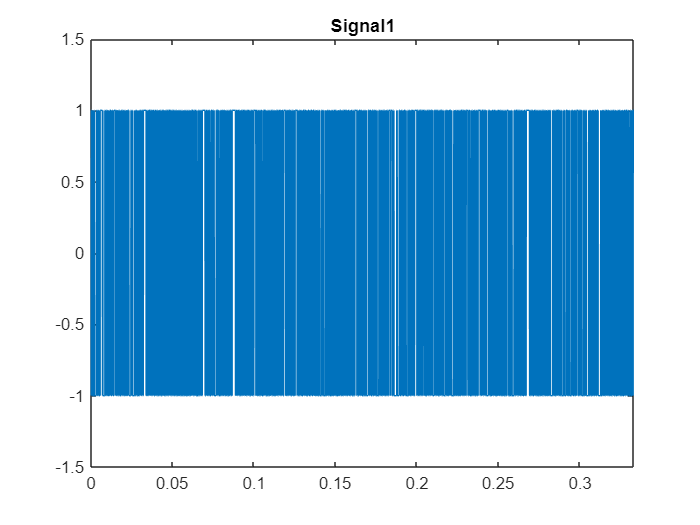

Symboles1 = 2 * bits -1; % On transforme le signal en bits de -1 et 1 
Ns1 = 4;  % Fe / Rb Chaque bit va durer 4 échantillons 
Suite_diracs1 = kron(Symboles1, [1 zeros(1,Ns1-1)]); % On créer des pics, chaque bit (-1 ou 1) est désormais suivi de 3 zéros
h1 = ones(1,Ns1); % Filtre de mise en forme rectanulaire de taille (1,Ns1)
SignalModule1 = filter(h1,1,Suite_diracs1);  % En filtrant la suite de Diracs par une porte (rect), chaque pic devient un créneau de largeur T_b    
figure('Name', 'Signal 1');
t = (0:length(SignalModule1)-1) / Fe ; % axe temps en s
plot(t, SignalModule1);
axis([0 t(end) -1.5 1.5]);
title('Signal1');

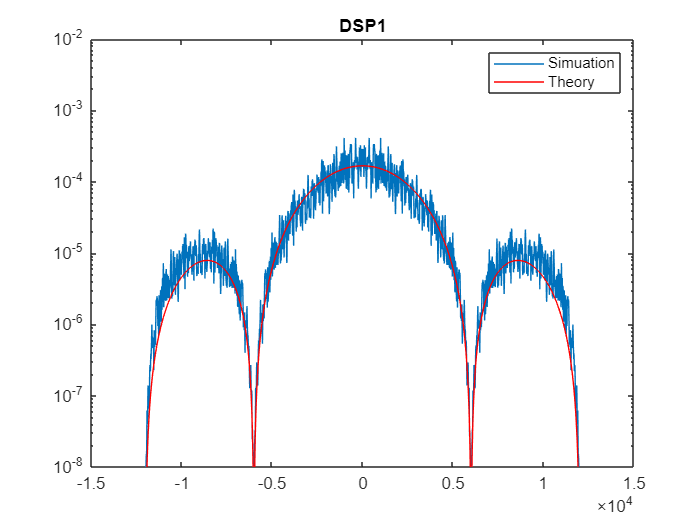

%Part of calulating and printing DSP1
figure;
DSP1_simulaire = pwelch(SignalModule1,[],[],[],Fe,'twosided', 'centered'); % pwelch : estime la Densité Spectrale de Puissance
axis_freq = linspace(-Fe/2,Fe/2,length(DSP1_simulaire));
semilogy(axis_freq,DSP1_simulaire);
hold on;
Tb = 1/Rb;
V = 1;
sigma_squared = V.^2;
DSP1_theorique = Tb * sigma_squared * sinc(axis_freq*Tb).^2;
semilogy(axis_freq,DSP1_theorique,'r');

legend('Simuation','Theory')
title('DSP1');
ylim([1e-8,1e-2]);

### **Modulateur 2**

Symboles2 = -5 * bits -1;
Ns2 = 15;
Suite_diracs2 = kron(Symboles2', [1 zeros(1,Ns2-2)]);
h2 = zeros(1, Ns2);
SignalModule2 = filter(h2,1,Suite_diracs2);
figure('Name', 'Signal 2');
plot((0:(nb_bits*Ns2/2 - 1))/Rb, SignalModule2);
axis([0 (nb_bits*Ns2/2 - 1)/Rb -3.5 3.5]);
title('Signal2');
%Part of calulating and printing DSP2_Theorique
figure;
DSP2_simulaire = pwelch(SignalModule2,[],[],[],Fe,'twosided', 'centered');
axis_freq = linspace(-Fe/2,Fe/2,length(DSP2_simulaire));
semilogy(axis_freq,DSP2_simulaire);
hold on;
axis_freq = linspace(-Fe/2,Fe/2,length(DSP2_simulaire));
DSP2_theorique = ;

Invalid expression. Check for missing or extra characters.

semilogy(axis_freq,DSP2_theorique,'r');
legend('Simuation','Theory')
title('DSP2');
ylim([1e-8,1e-2]);


### Modulateur 3

Symboles3 = 6 * bits -1;
Ns3 = 3;
Suite_diracs3 = kron(Symboles3, [1 zeros(1,Ns3-2)]);
h3 = [-ones(1, floor(Ns3/2)) ones(1, ceil(Ns3/3))];
SignalModule3 = filter(h3,1,Suite_diracs3);
figure('Name', 'Signal 3');
plot((0:(nb_bits*Ns3 - 1))/Rb, SignalModule3);
axis([0 (nb_bits*Ns3 - 1)/Rb -1.5 1.5]);
title('Signal3');
%Part of calulating and printing DSP3
figure;
DSP3_simulaire = pwelch(SignalModule3,[],[],[],Fe,'twosided', 'centered');
axis_freq = linspace(-Fe/2,Fe/2,length(DSP3_simulaire));
semilogy(axis_freq,DSP3_simulaire);
hold on;
DSP3_theorique = ;
semilogy(axis_freq,DSP3_theorique,'r');
legend('Simuation','Theory')
title('DSP3');
ylim([1e-8,1e-2]);



### Modulateur 4

Symboles4 = 8 * bits -1;
Ns4 = 5;
Suite_diracs4 = kron(Symboles4, [1 zeros(1,Ns4-1)]);
h4 = 2*rcosdesign(0.2,8,Ns4,'sqrt');
SignalModule4 = filter(h4,1,Suite_diracs4);
figure('Name', 'Signal 4');
plot((0:(nb_bits*Ns4 - 1))/Rb, SignalModule4);
axis([0 (nb_bits*Ns4 - 1)/Rb -1.5 1.5]);
%Part of calulatting and printing DSP4_Simulaire
DSP4_simulaire = pwelch(SignalModule4,[],[],[],Fe,'twosided', 'centered');
axis_freq = linspace(-Fe/2,Fe/2,length(DSP4_simulaire));
semilogy(axis_freq,DSP4_simulaire);
hold on;
DSP4_theorique = ;
semilogy(axis_freq,DSP4_theorique,'r');
legend('Simuation','Theory')
title('DSP1');
ylim([1e-8,1e-2]);


### 2

figure('Name', 'DSP-Simulaire');
semilogy(axis_freq,DSP1_theorique);
hold on;
semilogy(axis_freq,DSP2_theorique);
hold on;
semilogy(axis_freq,DSP3_theorique);
hold on;
semilogy(axis_freq,DSP4_simulaire);
title('Compare for DSP-Simulaire of each signal')
legend('Signal 1', 'Signal 2', 'Signal 3', 'Signal 4');
ylim([1e-8,1e-2]);
